# LTI System approximation 

`Longitudinal Acceleration Simulations`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`Check out the Equations of motion, Matlab Script, Simulink, and more at my github repository`

[`https://github.com/BrianLesko/LongitudinalVehicleDynamics`](https://github.com/BrianLesko/LongitudinalVehicleDynamics)

`Longitudinal Vehicle Modeling Series`

`7/24/23`

` Ohio State University`

## Estimated Velocity Torque Transfer function: Linear Time Invariant equation

    The above curves resemble the shape of 1- e^-t which is a simple linear time invariant equation. Generalized, it can be written with as k(1-e^-t/T) where K is a gain, or peak value, and T is the time constant, or about 63% of the rise time. This system is K/(Ts + 1) in the laplace domain 

To demonstrate the equivelence

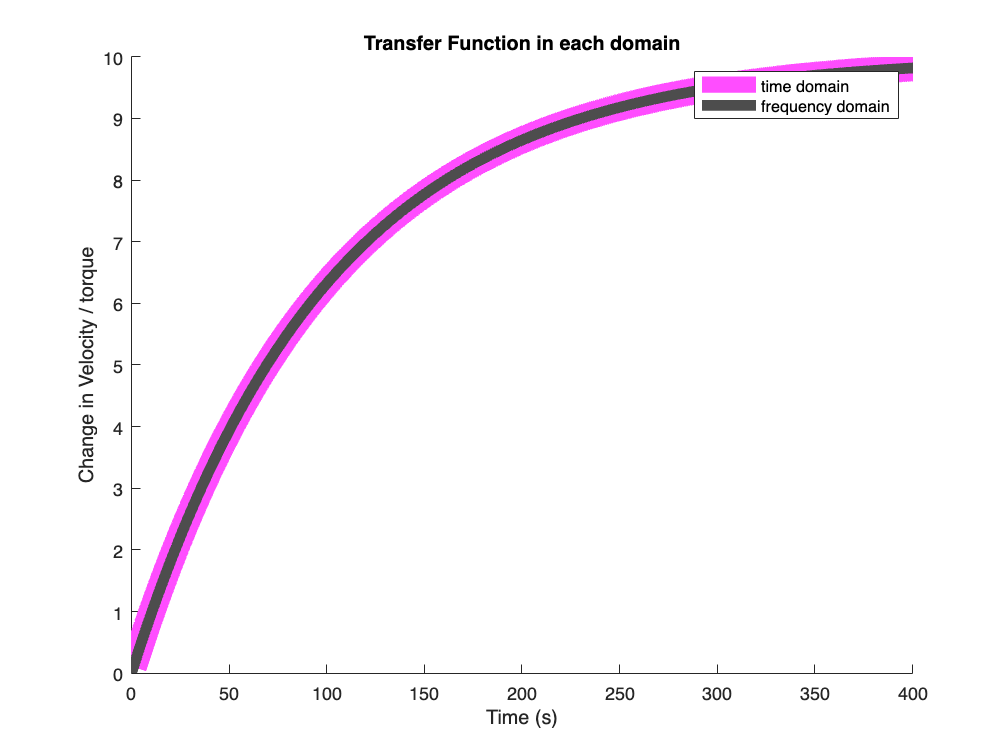

figure, hold on
plotLTIandTimeDomain()

With these rules, we can use the two parameter model to estimate each curve with a one pole zero root tranfer function. 

The error in this model can be seen in the difference between the two curves. 

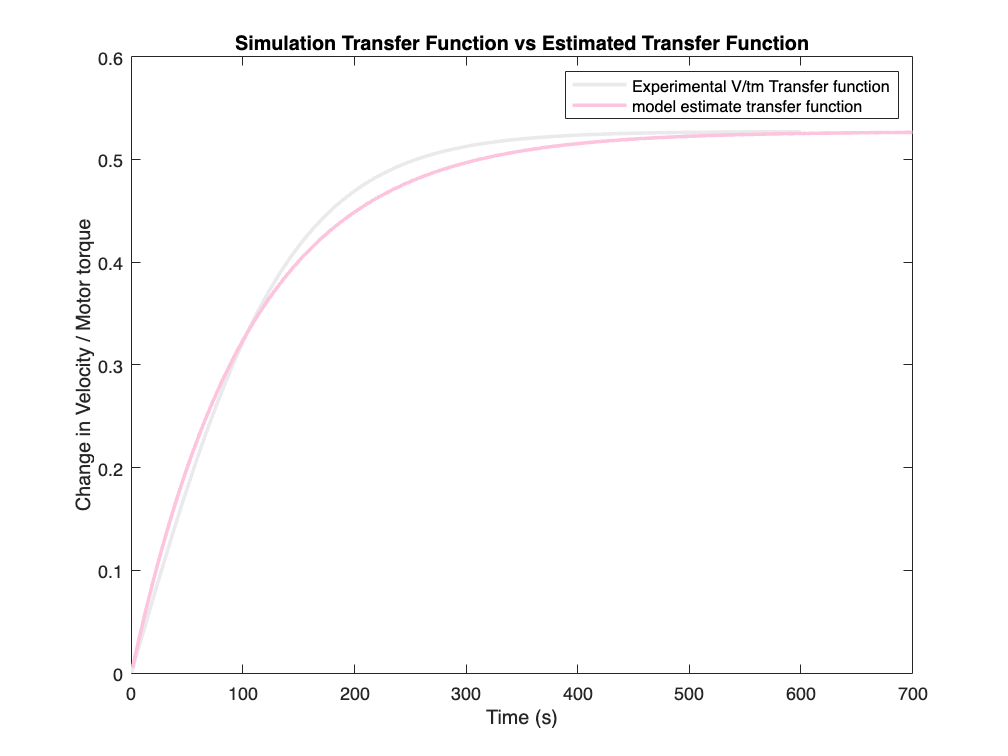

figure
load("vehicleCellsAccelerations.mat")
estimateLTI(vehicleCellsAcceleration(3)); 
title('Error at the smallest motor torque simulation '); legend('Experimental V/tm Transfer function','model estimate transfer function'); title('Simulation Transfer Function vs Estimated Transfer Function'); ylabel('Change in Velocity / Motor torque'); xlabel('Time (s)')

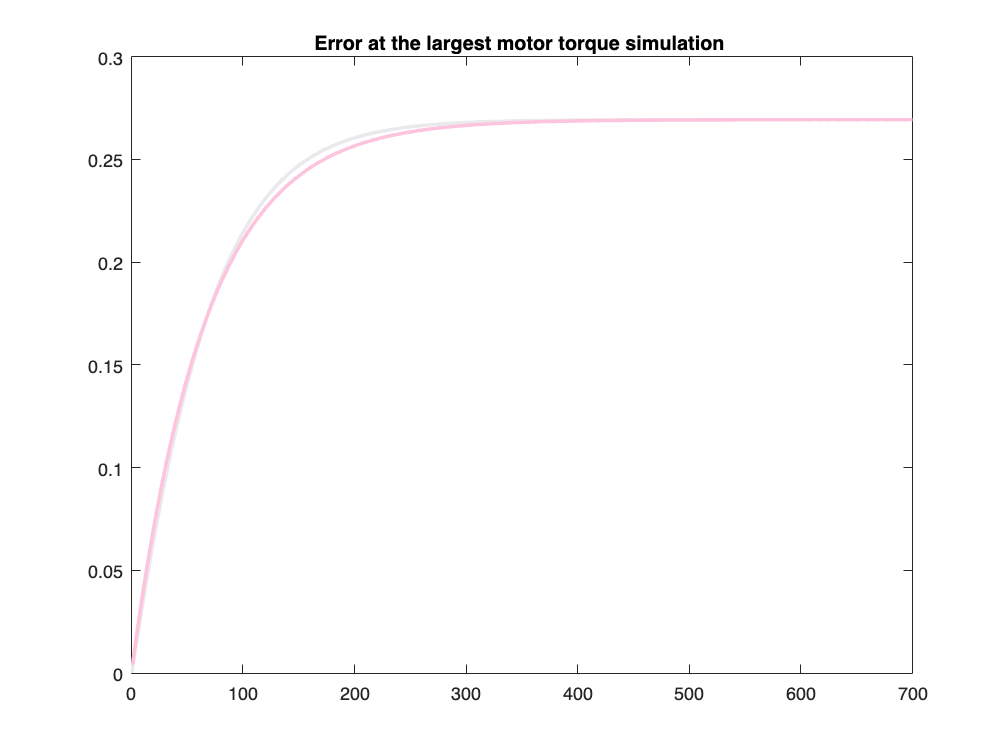

figure
estimateLTI(vehicleCellsAcceleration(20)); title('Error at the largest motor torque simulation ')

It works for decreasing systems too 

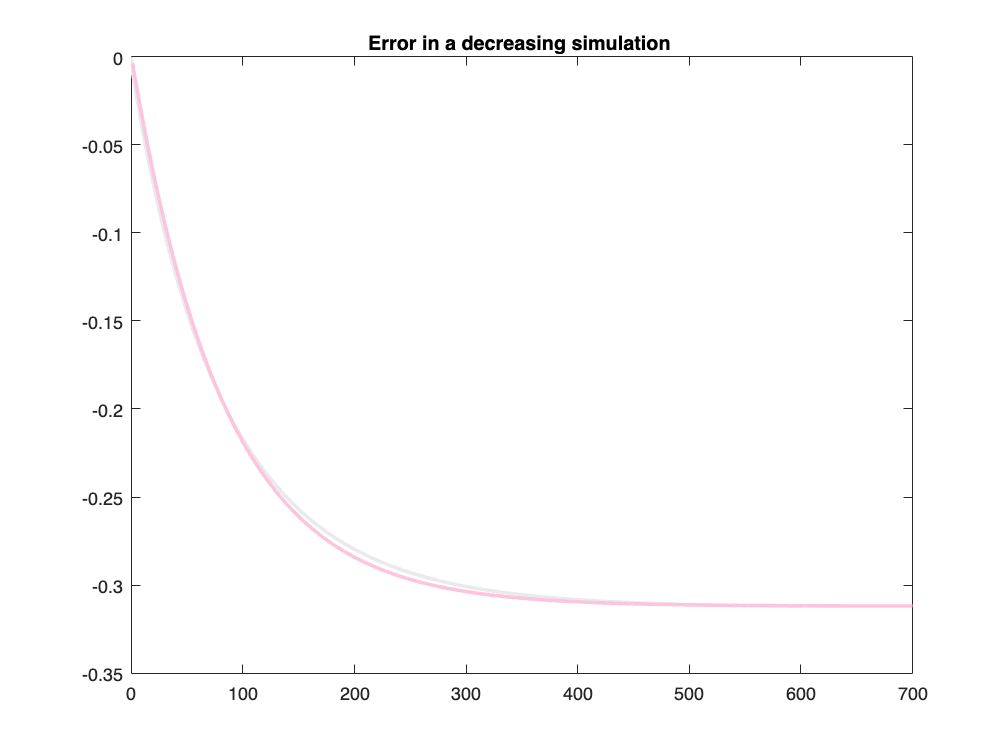

figure
estimateLTI(vehicleCellsAcceleration(29)); title('Error in a decreasing simulation ')

Lets now Estimte every acceleration simulation with this LTI system method

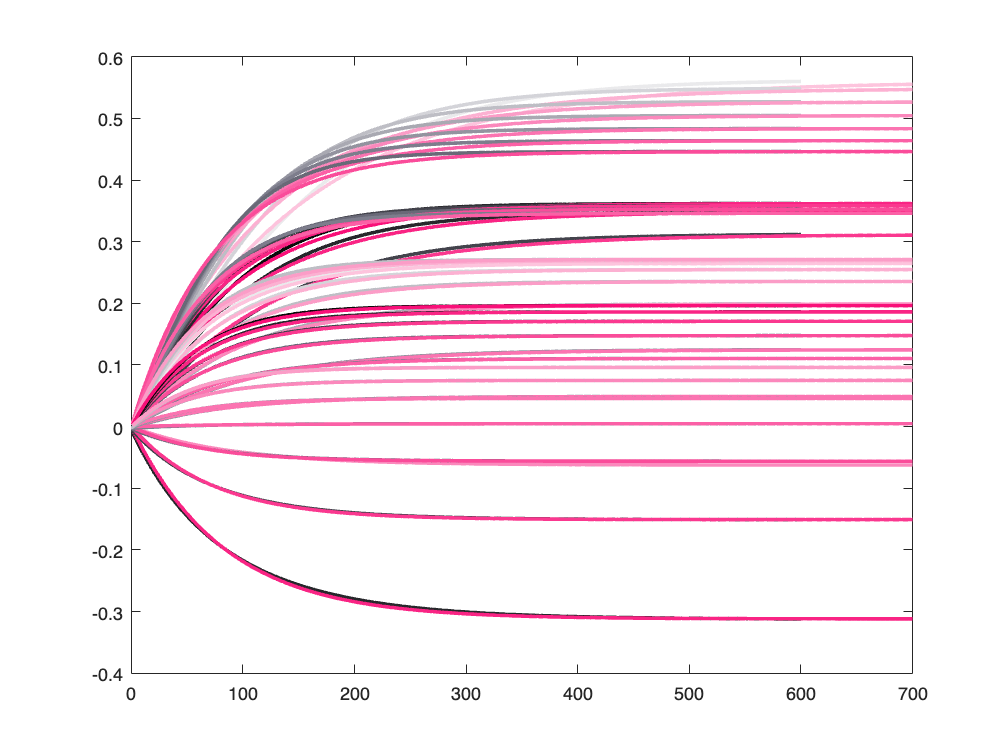

figure
params = estimateLTI(vehicleCellsAcceleration);

Lets just plot the LTI systems from the parameters

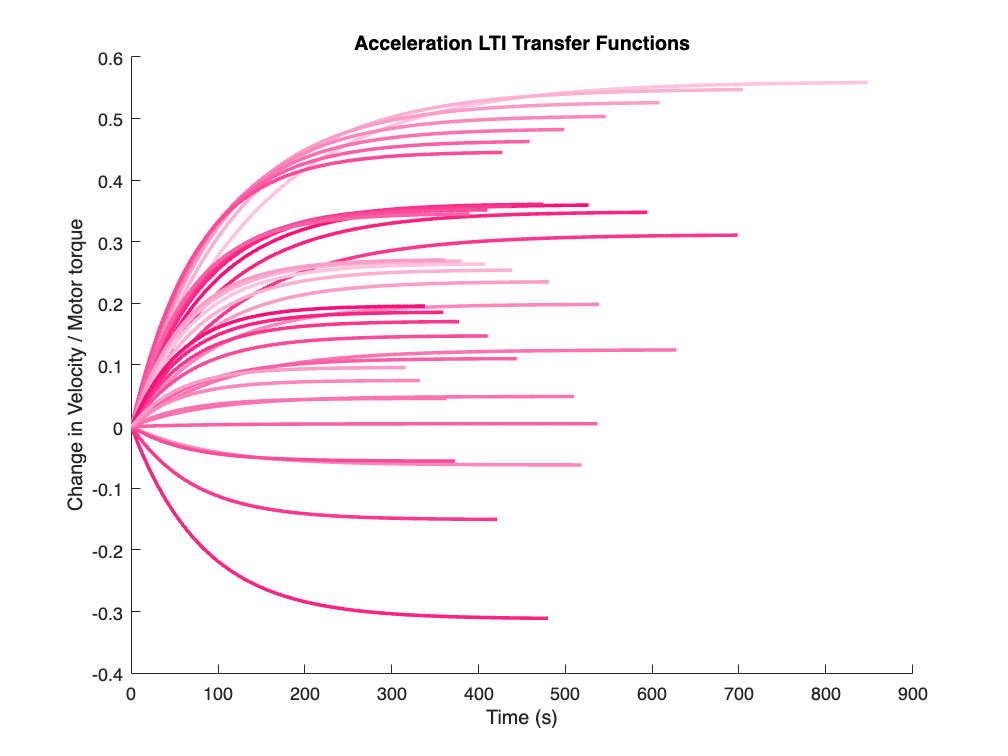

figure; hold on, plotLTI(params)
title('Acceleration LTI Transfer Functions'); ylabel('Change in Velocity / Motor torque'), xlabel('Time (s)')

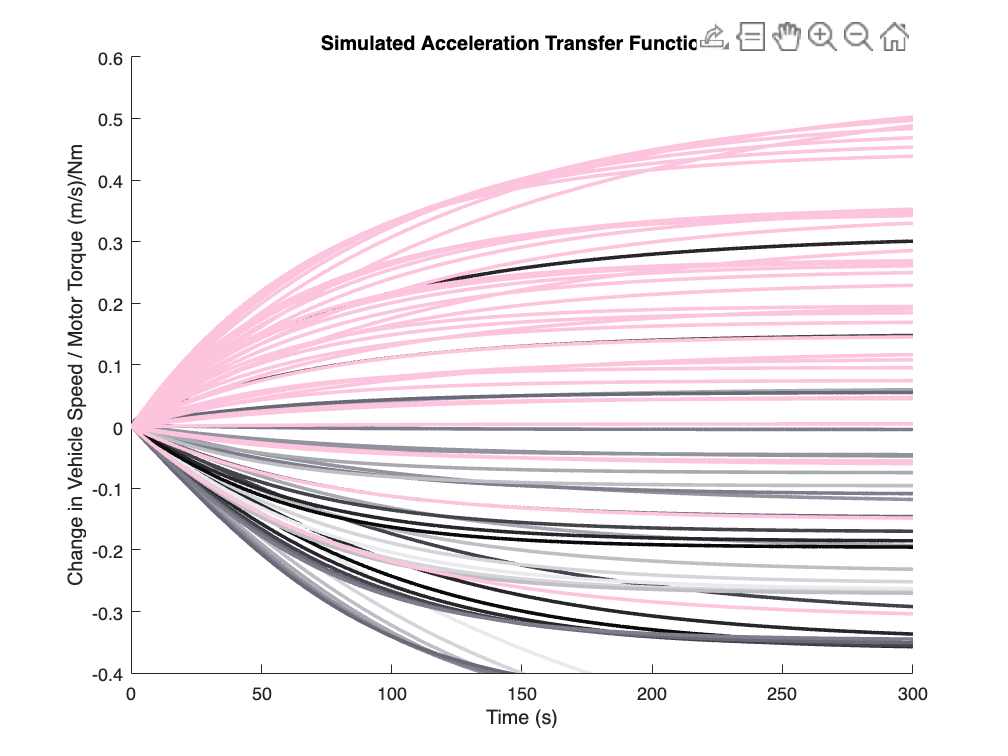

legendInfo = 1×35 cell array
    {'Motor Torque = 40'}    {'Motor Torque = 50'}    {'Motor Torque = 60'}    {'Motor Torque = 70'}    {'Motor Torque = 80'}    {'Motor Torque = 90'}    {'Motor Torque = 100'}    {'Motor Torque = 40'}    {'Motor Torque = 50'}    {'Motor Torque = 60'}    {'Motor Torque = 70'}    {'Motor Torque = 80'}    {'Motor Torque = 90'}    {'Motor Torque = 100'}    {'Motor Torque = 40'}    {'Motor Torque = 50'}    {'Motor Torque = 60'}    {'Motor Torque = 70'}    {'Motor Torque = 80'}    {'Motor Torque = 90'}    {'Motor Torque = 100'}    {'Motor Torque = 40'}    {'Motor Torque = 50'}    {'Motor Torque = 60'}    {'Motor Torque = 70'}    {'Motor Torque = 80'}    {'Motor Torque = 90'}    {'Motor Torque = 100'}    {'Motor Torque = 40'}    {'Motor Torque = 50'}    {'Motor Torque = 60'}    {'Motor Torque = 70'}    {'Motor Torque = 80'}    {'Motor Torque = 90'}    {'Motor Torque = 100'}


legendInfo = aniSimCellsLTI(vehicleCellsAcceleration, params)

# Functions 

function plotLTIandTimeDomain()
    K = 10; T = 100;

    % time domain 
    time = 1:1:700;  e = 2.71828;
    velocity = K * (1-e.^(-time/T)); % step response at (Tm-Tb)
    plot(time,velocity,'Linewidth',15,'Color', [1,.3,1])
    
    % Frequency domain 
    s = tf('s');
    LTI = K/ (T*s + 1);
    [h,g] = step(LTI);
    plot(g, h, 'Color', [.3,.3,.3],'LineWidth',6)
    axis([0 400 0 10])

    legend('time domain','frequency domain')
    title('Transfer Function in each domain')
    ylabel('Change in Velocity / torque'), xlabel('Time (s)')
end 

function params = estimateLTI(simCells)
    colors = getColors(); colors2 = getColors2();
    n = length(simCells);
    e = 2.71828;
    params = zeros(n,2);
    for i = 1:1:n
        % retreive sim data
        time = simCells{i}.time; V = simCells{i}.V; Tm = simCells{i}.Tm; Tb = simCells{i}.Tb;
    
        x = time;
        y = (V-V(1))./(Tm-Tb); 

        l = length(time);

        if Tm(1) > 0 
            if V(1)/Tm(1) < V(l)/Tm(l) % increasing system
                % estimating the parameters for the LTI
                peak_value = max(y);
                % Find the time at which the response is 63% of the peak value
                [~, index] = min(abs(y - 0.632*peak_value));
                t_63 = x(index);
            
                K = peak_value;
                T = t_63;
            end     
            if V(1)/Tm(1) > V(l)/Tm(l) % decreasing system
                peak_value = min(y);
                % Find the time at which the response is 63% of the peak value
                [~, index] = min(abs(y - 0.632*peak_value));
                t_63 = x(index);
                K = peak_value;
                T = t_63;
            end 
        end 
        params(i,:) = [K, T]; 
 
        color = colors(i); color2 = colors2(i);
        plot(x,y,'Linewidth',2,'Color',color), hold on

        % time domain 
        time = 1:1:700;  e = 2.71828;
        velocity = K * (1-e.^(-time/T)); % step response at (Tm-Tb)
        plot(time,velocity,'Linewidth',2,'Color', color2)
    end 
end 

function plotLTI(params)
    n = length(params(:,1));
    colors2 = getColors2();
    for i = 1:1:n
        param = params(i,:);
        K = param(1); T = param(2);
    
        s = tf('s');
        LTI = K/ (T*s + 1);
        [h,g] = step(LTI);
        
        color2 = colors2(i);
        plot(g, h, 'Color', color2,'LineWidth',2)
    end 
end 
function colors = getColors()
    a = "#0A0A0A"; % night
    %b = "#131315"; % night 
    %c = "#1D1D20"; % eerie black
    d = "#27272B"; % raisin black
    %e = "#303036"; % jet
    %f = "#3A3A41"; % onyx
    g = "#43434C"; % onyx
    %h = "#565661"; % davy"s gray
    %i = "#60606C"; % dim gray
    j = "#696977"; % dim gray
    %k = "#737382"; % slate gray
    l = "#7D7D8C"; % taupe gray
    m = "#93939F"; % cool gray
    n = "#A9A9B2"; % french gray
    o = "#BEBEC5"; % french gray
    p = "#D4D4D9"; % platinum
    q = "#EAEAEC"; % anti-flash white

    colors = [q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a]; 
end     

function colors = getColors2()
    a = "#F91079"; 
    d = "#F92484"; 
    g = "#FA388F"; 
    j = "#FA4C9A"; 
    l = "#FB60A6"; 
    m = "#FB74B1"; 
    n = "#FB88BC"; 
    o = "#FB9DC7"; 
    p = "#FCB1D2"; 
    q = "#FDC4DD"; 

    colors = [q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a,d,g,j,l,m,n,o,p,q,p,o,n,m,l,j,g,d,a]; 
end  

Animation Functions 

function legendInfo = aniSimCellsLTI(simCells, params)
    n = length(simCells(1,:));
    colors = getColors();

    figure;
    hold on;

    % Pre-plotting to get the axes limits
    for i = 1:1:n
        time = simCells{i}.time;
        dVTm = (-simCells{i}.V(1)+simCells{i}.V)/simCells{i}.Tm;
        plot(time,dVTm,'Color',"#FFFFFF");
    end

    % Get the current axes limits
    ax = gca;
    xl = [0 300];
    yl = ax.YLim;

    % Clear the axes
    cla;

    title('Simulated Acceleration Transfer Functions'), xlabel('Time (s)'), ylabel('Change in Vehicle Speed / Motor Torque (m/s)/Nm')

    % Initialize animated lines
    h = gobjects(1, n);
    for i = 1:1:n
        color = colors(i);
        h(i) = animatedline('Color', color, 'LineWidth', 2);
        ax = gca;
        ax.XLim = xl;
        ax.YLim = yl;
    end

    % Add points to all lines, updating the plot as we go
    for j = 1:length(simCells{1}.time)
        for i = 1:1:n
            time = simCells{i}.time;
            dVTm = (simCells{i}.V(1)-simCells{i}.V)/simCells{i}.Tm;
            addpoints(h(i), time(j), dVTm(j));
            
            % If the current x-value is around 300, plot the LTI function using the corresponding parameters
            if time(j) >= 300
                plotLTI(params(i,:));  % Plot the LTI function using the parameters corresponding to the current simCell
            end
        end
        if mod(j,2) == 0 % update the plot every n points
            drawnow;
        end
    end

    % Add legend information
    for i = 1:1:n
        Tm = simCells{i}.Tm(1); % (1) because the motor torque is constant
        legendInfo{i} = sprintf('Motor Torque = %s', num2str(Tm));
    end 
    hold off;
end